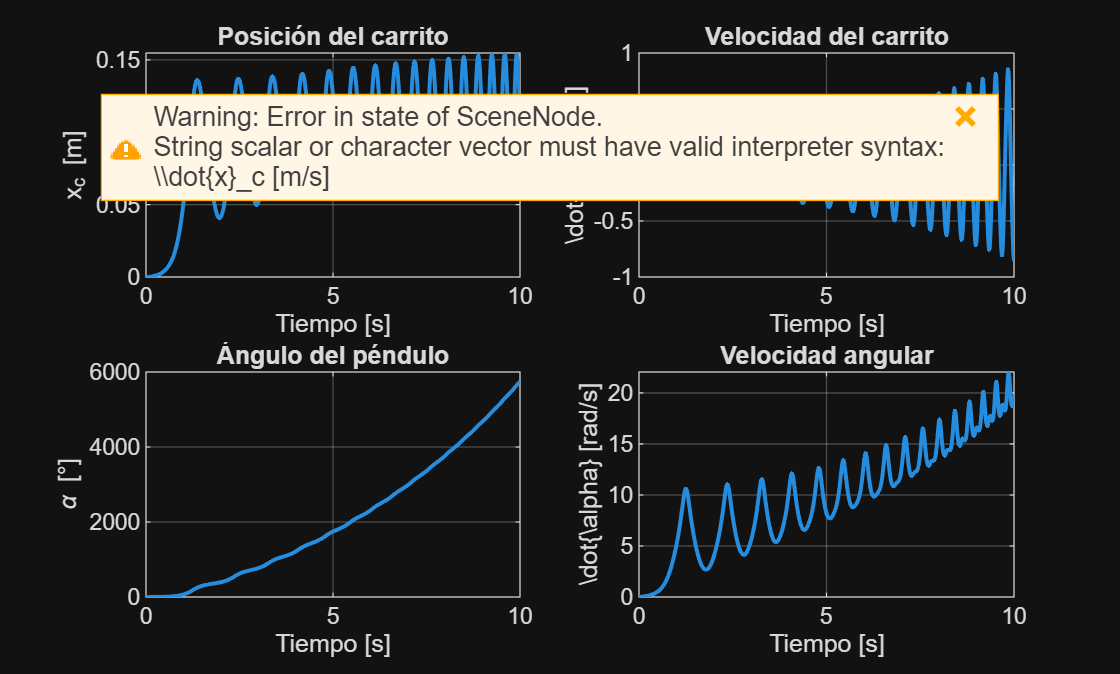

% Este programa esta en un livescript, es un .mlx

clear; clc; 

Ip  = 0.0079;     % kg*m^2
Mc  = 0.7031;     % kg
lp  = 0.3302;     % m
Mp  = 0.23;       % kg
Fc  = 0;          % N
Beq = 4.3;        % N*s/m
g   = 9.81;       % m/s^2
Bp  = 0.0024;     % N*m*s/rad

%% Condiciones iniciales

x0 = [ ...
    0;            % xc
    0;            % xdotc
    pi/180;       % alpha (1 grado)
    0             % alphadot
];

tspan = [0 10];

%% Simulación del sistema

[t, x] = ode45(@pendulo_invertido, tspan, x0);

%% Resultados

figure
subplot(2,2,1)
plot(t, x(:,1), 'LineWidth',1.5)
grid on
xlabel('Tiempo [s]')
ylabel('x_c [m]')
title('Posición del carrito')

subplot(2,2,2)
plot(t, x(:,2), 'LineWidth',1.5)
grid on
xlabel('Tiempo [s]')
ylabel('\dot{x}_c [m/s]')
title('Velocidad del carrito')

subplot(2,2,3)
plot(t, x(:,3)*180/pi, 'LineWidth',1.5)
grid on
xlabel('Tiempo [s]')
ylabel('\alpha [°]')
title('Ángulo del péndulo')

subplot(2,2,4)
plot(t, x(:,4), 'LineWidth',1.5)
grid on
xlabel('Tiempo [s]')
ylabel('\dot{\alpha} [rad/s]')
title('Velocidad angular')



%% Función dinámica del péndulo invertido
function dx = pendulo_invertido(t, x)
sin(t); % Es solo para quitar una adevertencia
Ip  = 0.0079;
Mc  = 0.7031;
lp  = 0.3302;
Mp  = 0.23;
Fc  = 0;
Beq = 4.3;
g   = 9.81;
Bp  = 0.0024;

% Variables de estado
xc      = x(1); sin(xc); % El sin(xc), es tambien para quitar una advertencia
xdotc   = x(2);
alpha   = x(3);
alphad  = x(4);

% Denominador comun

D = (Mc + Mp)*Ip + Mc*Mp*lp^2 + Mp^2*lp^2*sin(alpha)^2;

% Ecuacion de x dos puntos

xddot = ( ...
    (Ip + Mp*lp^2)*Fc ...
    + Mp^2*lp^2*g*cos(alpha)*sin(alpha) ...
    - (Ip + Mp*lp^2)*Beq*xdotc ...
    - (Ip*Mp*lp - Mp^2*lp^3)*alphad^2*sin(alpha) ...
    - Mp*lp*Bp*alphad*cos(alpha) ...
    ) / D;

% Ecuacion de alpha dos puntos

alphadd = ( ...
    (Mc + Mp)*Mp*g*lp*sin(alpha) ...
    - (Mc + Mp)*Bp*alphad ...
    + Fc*Mp*lp*cos(alpha) ...
    - Mp^2*lp^2*alphad^2*sin(alpha)*cos(alpha) ...
    - Beq*Mp*lp*xdotc*cos(alpha) ...
    ) / D;

dx = zeros(4,1);
dx(1) = xdotc;
dx(2) = xddot;
dx(3) = alphad;
dx(4) = alphadd;

end

% El programa marca otra advertencia a la hora de graficar
% esto aparentemente es porque existe un problema con su
% interpretacion de latex, en un livescript.